set(groot,'defaultTextInterpreter','latex');
set(groot,'defaultAxesTickLabelInterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

filename = "analytic_CPn_density_n32_a0.100_p650_k2-150.csv";
Analytical_Matrix = readmatrix(filename);

step_size_grid = (2/pi) * Analytical_Matrix(1, 2:end);
Analytical_PDF  = (pi/2) * Analytical_Matrix(2:end, 2:end);

Selected_Steps = [2, 5, 10, 25, 50, 100, 150];

Residuals   = zeros(numel(Selected_Steps), numel(step_size_grid));
L2_errors   = zeros(numel(Selected_Steps), 1);
Linf_errors = zeros(numel(Selected_Steps), 1);

plot_colours = lines(numel(Selected_Steps));

% ------------------------------------------------------------
% Figure 1: Simulated vs analytical densities
% ------------------------------------------------------------

figure('Name', 'Random Walk Algorithm Benchmarking');
hold on

legend_entries = cell(1, 2*numel(Selected_Steps));

for i = 1:numel(Selected_Steps)

    j = Selected_Steps(i);

    RWA_data_index        = j - 1;
    Analytical_data_index = j - 1;

    Samples = RWA_Samples(:, RWA_data_index);
    Samples = Samples(:);
    Samples = Samples(isfinite(Samples));

    [RWA_TPDF, ~, bw] = ksdensity(Samples, step_size_grid, 'Support', [0, 1], 'BoundaryCorrection', 'reflection');

    Analytic_Row = Analytical_PDF(Analytical_data_index, :);

    plot(step_size_grid, RWA_TPDF, '-',  'LineWidth', 1.8, 'Color', plot_colours(i,:));
    plot(step_size_grid, Analytic_Row, '--', 'LineWidth', 1.8, 'Color', plot_colours(i,:));

    legend_entries{2*i - 1} = sprintf('RWA KDE $k=%d$', j);
    legend_entries{2*i}     = sprintf('Analytical $k=%d$', j);

    fprintf('Number of Steps (k) = %3d | Kernel Density Estimation Bandwidth = %.4e\n', j, bw);
end

Number of Steps (k) =   2 | Kernel Density Estimation Bandwidth = 4.2906e-04
Number of Steps (k) =   5 | Kernel Density Estimation Bandwidth = 8.4756e-04
Number of Steps (k) =  10 | Kernel Density Estimation Bandwidth = 1.2636e-03
Number of Steps (k) =  25 | Kernel Density Estimation Bandwidth = 2.0281e-03
Number of Steps (k) =  50 | Kernel Density Estimation Bandwidth = 2.8328e-03
Number of Steps (k) = 100 | Kernel Density Estimation Bandwidth = 3.8237e-03
Number of Steps (k) = 150 | Kernel Density Estimation Bandwidth = 4.4567e-03


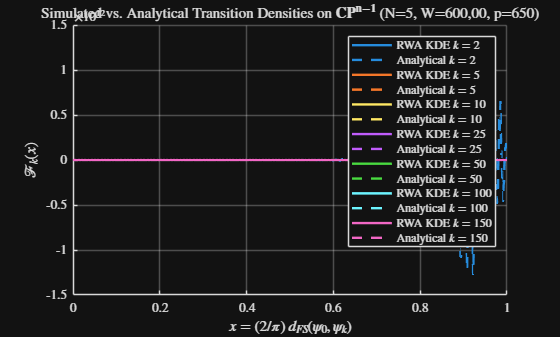


xlabel('$x = (2/\pi)\,d_{FS}(\psi_0,\psi_k)$');
ylabel('$\mathcal{F}_k(x)$');
title('Simulated vs. Analytical Transition Densities on $\bf{CP}^{n-1}$ (N=5, W=600,00, p=650)');
legend(legend_entries, 'Location', 'north east');
xlim([0, 1]);
grid on
hold off

exportgraphics(gcf, 'transition_densities_KDE_N=5.png', 'Resolution', 300);


% ------------------------------------------------------------
% Figure 2: Residuals
% ------------------------------------------------------------

figure('Name', 'Residual Errors (Algorithm vs. Analytical)');
hold on

for i = 1:numel(Selected_Steps)

    j = Selected_Steps(i);

    RWA_data_index        = j - 1;
    Analytical_data_index = j - 1;

    Samples = RWA_Samples(:, RWA_data_index);
    Samples = Samples(:);
    Samples = Samples(isfinite(Samples));

    [RWA_TPDF, ~] = ksdensity(Samples, step_size_grid, 'Support', [0, 1], 'BoundaryCorrection', 'reflection');

    Analytic_Row = Analytical_PDF(Analytical_data_index, :);

    Residual = RWA_TPDF - Analytic_Row;

    Residuals(i, :) = Residual;

    dx = mean(diff(step_size_grid));
    L2_errors(i)   = sqrt(trapz(step_size_grid, Residual.^2));
    Linf_errors(i) = max(abs(Residual));

    plot(step_size_grid, Residual, 'LineWidth', 1.8, 'Color', plot_colours(i,:));

    fprintf('k = %3d | L2 = %.3e | Linf = %.3e\n', ...
        j, L2_errors(i), Linf_errors(i));
end

k =   2 | L2 = 2.308e+11 | Linf = 1.336e+12
k =   5 | L2 = 1.500e+06 | Linf = 8.506e+06
k =  10 | L2 = 4.397e+01 | Linf = 2.114e+02
k =  25 | L2 = 1.306e-02 | Linf = 1.407e-01
k =  50 | L2 = 1.426e-02 | Linf = 6.795e-02
k = 100 | L2 = 1.035e-02 | Linf = 5.692e-02
k = 150 | L2 = 1.077e-02 | Linf = 5.484e-02


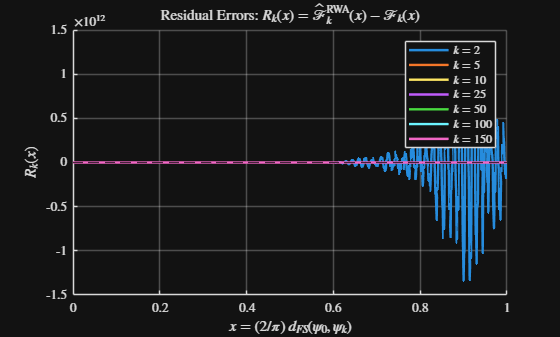


yline(0, 'k--', 'LineWidth', 1);
xlabel('$x = (2/\pi)\,d_{FS}(\psi_0,\psi_k)$');
ylabel('$R_k(x)$');
title('Residual Errors: $R_k(x)=\hat{\mathcal{F}}_k^{\mathrm{RWA}}(x)-\mathcal{F}_k(x)$');
legend(arrayfun(@(k) sprintf('$k=%d$', k), Selected_Steps, 'UniformOutput', false), ...
    'Location', 'north east');
xlim([0, 1]);
grid on
hold off

exportgraphics(gcf, 'Residuals_KDE_N=5.png', 'Resolution', 300);


%{
set(groot,'defaultTextInterpreter','latex');
set(groot,'defaultAxesTickLabelInterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

filename = "analytic_CPn_density_n8_a0.100_p500_k2-150.csv";

Analytical_Results = readmatrix(filename);

step_size_grid = (2/pi) * Analytical_Results(1, 2:end);
Analytical_PDF = (pi/2) * Analytical_Results(2:end, 2:end);

Num_Bins    = 2000;
Bin_Edges   = linspace(0, 1, Num_Bins + 1);
Bin_Centers = 0.5 * (Bin_Edges(1:end-1) + Bin_Edges(2:end));

Selected_Steps = [2, 5, 10, 25, 50, 100, 150];

Residuals   = zeros(numel(Selected_Steps), numel(step_size_grid));
L2_errors   = zeros(numel(Selected_Steps), 1);
Linf_errors = zeros(numel(Selected_Steps), 1);

plot_colours = lines(numel(Selected_Steps));

figure('Name', 'Random Walk Algorithm Benchmarking');
hold on

legend_entries = cell(1, 2*numel(Selected_Steps));

for i = 1:numel(Selected_Steps)

    j = Selected_Steps(i);

    RWA_data_index  = j - 1;
    Analytical_data_index = j - 1;  

    RWA_Data = RWA_Samples(:, RWA_data_index);
    Data_Counts  = histcounts(RWA_Data, Bin_Edges, 'Normalization', 'pdf');

    Analytical_Results = Analytical_PDF(Analytical_data_index, :);

    plot(Bin_Centers, Data_Counts, '-',  'LineWidth', 1.5, 'Color', plot_colours(i,:));
    plot(step_size_grid, Analytical_Results, '--', 'LineWidth', 1.5, 'Color', plot_colours(i,:));

    legend_entries{2*i - 1} = sprintf('RWA $k=%d$', j);
    legend_entries{2*i}     = sprintf('Analytical $k=%d$', j);
end

xlabel('$x = (2/\pi)\,d_{FS}(\psi_0,\psi_k)$');
ylabel('$\mathcal{F}_k(x)$');
title('Simulated and Analytical Transition Densities (N=3, W=750,000, p=500)');
legend(legend_entries, 'Location', 'north east');
xlim([0, 1]);
grid on
hold off
exportgraphics(gcf, 'transition_densities_N=3.png', 'Resolution', 300);

figure('Name', 'Residuals: Random Walk - Analytical');
hold on

for i = 1:numel(Selected_Steps)

    j = Selected_Steps(i);

    RWA_data_index  = j - 1;
    Analytical_data_index = j - 1;

    RWA_Data = RWA_Samples(:, RWA_data_index);
    Data_Counts  = histcounts(RWA_Data, Bin_Edges, 'Normalization', 'pdf');

    MC_on_analytic_grid = interp1(Bin_Centers, Data_Counts, step_size_grid, 'linear', 0);
    Analytical_Results            = Analytical_PDF(Analytical_data_index, :);

    Residual = MC_on_analytic_grid - Analytical_Results;

    Residuals(i, :) = Residual;
    L2_errors(i)    = norm(Residual, 2);
    Linf_errors(i)  = max(abs(Residual));

    plot(step_size_grid, Residual, 'LineWidth', 1.5, 'Color', plot_colours(i,:));

    fprintf('k = %3d | mc col = %3d | ana row = %3d | L2 = %.3e | Linf = %.3e\n', ...
        j, RWA_data_index, Analytical_data_index, L2_errors(i), Linf_errors(i));
end

yline(0, 'k--', 'LineWidth', 1);
xlabel('$x = (2/\pi)\,d_{FS}(\psi_0,\psi_k)$');
ylabel('$R_k(x)$');
title('Residual Errors: $R_k(x)=\mathcal{F}_k^{\mathrm{RWA}}(x)-\mathcal{F}_k(x)$');
legend(arrayfun(@(k) sprintf('$k=%d$', k), Selected_Steps, 'UniformOutput', false), ...
    'Location', 'north east');
xlim([0, 1]);
grid on
hold off
%exportgraphics(gcf, 'Residuals_N=4.png', 'Resolution', 300);
%}